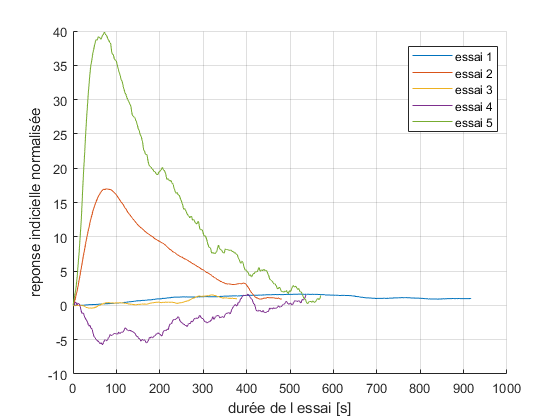

%avec boucle
ysp=A(:,4);
a=diff(ysp);
ydif=a(a~=0);
xdif=find(a~=0);
clf; hold on; grid on

N = 4;   % A CHANGERRRR nombre d'essais FAUT CHANGER ICI SI CA DIT Index exceeds the number of array elements
for k = 1:N
    bi = xdif(k);      
    bf = xdif(k+1);    
    
    idx = bi:bf;
    yk = y(idx);

   
    y0 = yk(1);
    yk = yk - y0;

    % normalisation
    yinf = mean(yk(max(1,end-10):end));   % moyenne des 10 derniers points
    yk = yk / yinf;

    t0 = idx - bi;
    plot(t0, yk);
end

% ---- DERNIER ESSAI : de xdif(end) jusqu'à la fin ----
bi = xdif(end);
bf = length(y);           % ou bf = length(t) si t existe et même taille

idx = bi:bf;
yk = y(idx);

y0 = yk(1);
yk = yk - y0;

yinf = mean(yk(max(1,end-10):end));
yk = yk / yinf;

t0 = idx - bi;
plot(t0, yk);


legend(compose("essai %d", 1:(N+1)), 'Location','best')
xlabel('durée de l essai [s]')
ylabel('reponse indicielle normalisée')


%Lancer simulink ,LAISSER ATTEINDRE LE REGIME EPRMANENT
%  faire ton scope , stoper la simulation, cliquer sur mise
%en forme indent
%remplacer le N par nombre echelon - 1 et lancer le code 

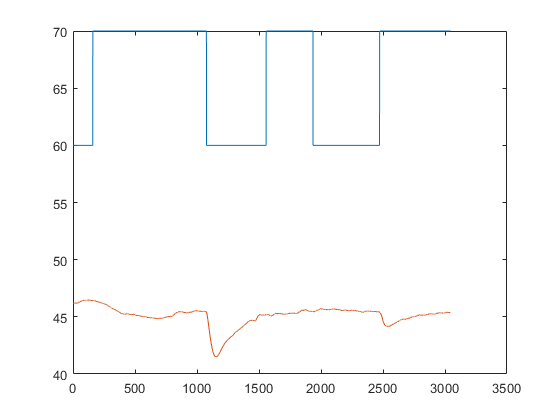

clf;
plot(t,A(:,4),t,y)

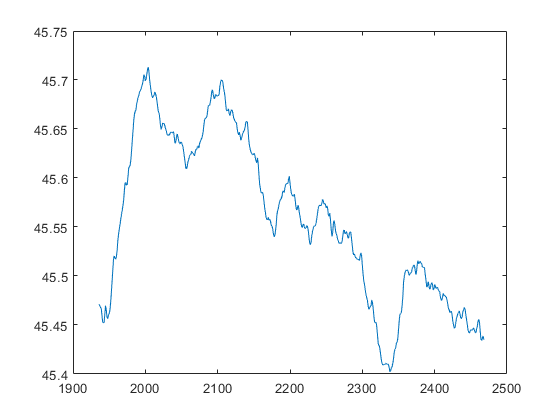

clf;
y2=y(1936:2468);
t2=1936:1:2468;

plot(t2,y2);

t3=2468:1:3044

t3 =         2468        2469        2470        2471        2472        2473        2474        2475        2476        2477        2478        2479        2480        2481        2482        2483        2484        2485        2486        2487        2488        2489        2490        2491        2492        2493        2494        2495        2496        2497        2498        2499        2500        2501        2502        2503        2504        2505        2506        2507        2508        2509        2510        2511        2512        2513        2514        2515        2516        2517


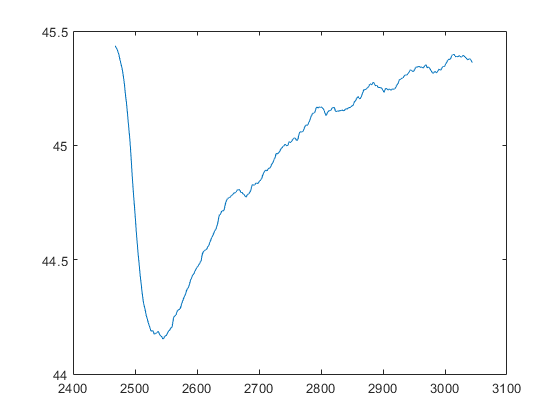

plot(t3,y(t3))


t22=t2-t2(1)

t22 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


t33=t3-t3(1)

t33 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


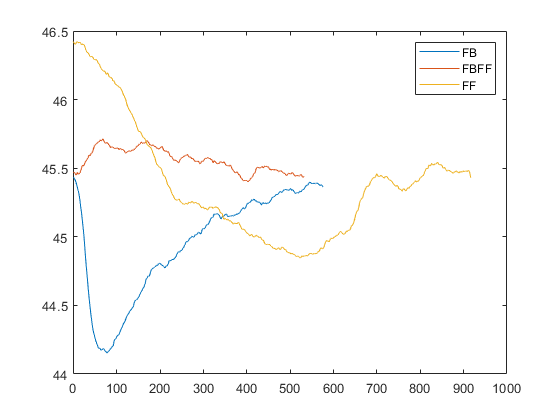

t11=t(159:1076)-159;
plot(t33,y(t3),t22,y2,t11,y(159:1076))
legend('FB','FBFF','FF')